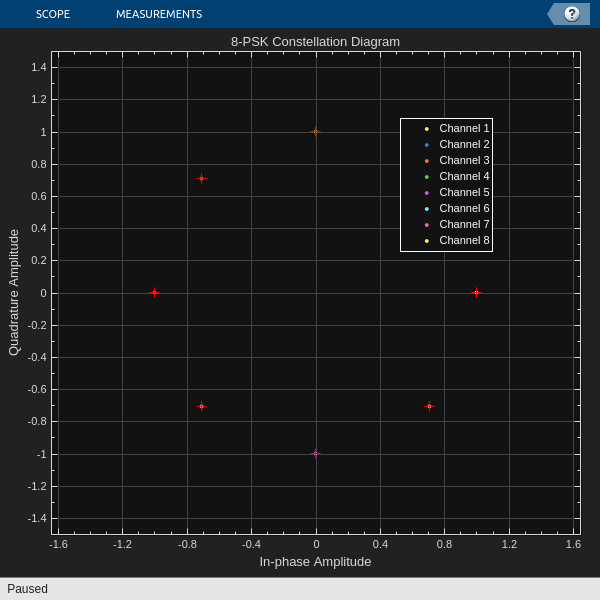

% MATLAB script for 8-PSK Constellation and Decision Regions

% Define 8-PSK symbols
M = 8; % Number of symbols
angles = (0:M-1) * 2 * pi / M; % 8 equidistant angles
symbols = exp(1j * angles); % 8-PSK symbols in polar form

% Generate sample signal for the constellation diagram
sampleSignal = symbols; % Use symbols as input data

% Create and configure the constellation diagram object
hConstDiagram = comm.ConstellationDiagram( ...
    'ReferenceConstellation', symbols, ... % Reference points for 8-PSK
    'XLimits', [-1.5, 1.5], ...
    'YLimits', [-1.5, 1.5], ...
    'Title', '8-PSK Constellation Diagram', ...
    'ShowGrid', true);

% Plot the constellation diagram
step(hConstDiagram, sampleSignal); % Provide the input signal for plotting

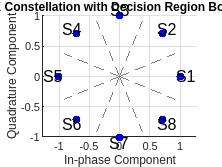


% Manually add decision region boundaries
figure; % Create a new figure for the decision regions
theta_boundaries = (0:M-1) * 2 * pi / M + pi / M; % Boundaries between decision regions
for k = 1:M
    % Plot lines for decision region boundaries
    line_x = [0 cos(theta_boundaries(k))];
    line_y = [0 sin(theta_boundaries(k))];
    hold on;
    plot(line_x, line_y, '--', 'Color', [0.5 0.5 0.5]);
end

% Overlay the constellation points
scatter(real(symbols), imag(symbols), 'b', 'filled');
text(real(symbols) * 1.1, imag(symbols) * 1.1, arrayfun(@(i) sprintf('S%d', i), 1:M, 'UniformOutput', false), ...
    'FontSize', 12, 'HorizontalAlignment', 'center');

% Add axis and labels
axis equal;
grid on;
xlabel('In-phase Component');
ylabel('Quadrature Component');
title('8-PSK Constellation with Decision Region Boundaries');